# MDM Time delay

The purpose of this exercise is the prediction of the population of two species (Snowshoe Hare and Canada Lynx), respectively, predator and prey of each other. Now will try to use the time delay scheme to DMD and optDMD as in the previous point. (Chiede di determinare se sono **latent variable. (?)**)

Exercise start with data declaratio

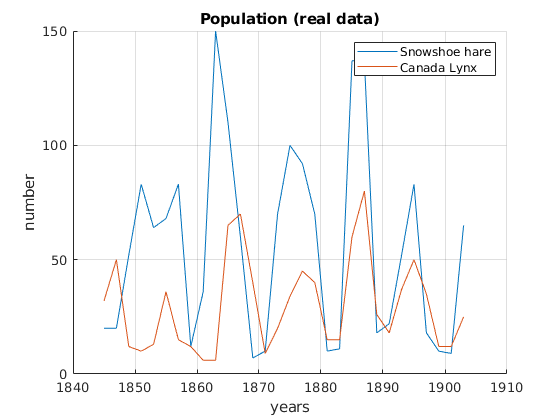

load_data
figure
hold on
plot(years, snowshoe_hare)
plot(years, canada_lynx)
grid on
xlabel("years")
ylabel("number")
title("Population (real data)")
legend("Snowshoe hare","Canada Lynx")

X = [snowshoe_hare; canada_lynx];

I can start builiding an Hankel matrix formed by the series of delayed data:

time_delay = 2;
H = hank(X,time_delay);
complete_rank = time_delay*2;

Now I can try to apply DMD to this series of data.

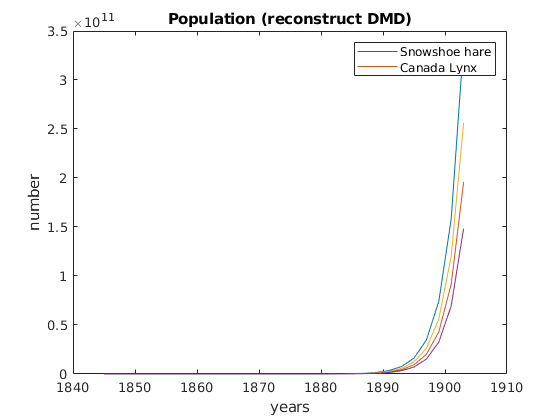

[phi_dmd, lambda_dmd, b_dmd] = DMD(H(:,1:end-1), H(:,2:end),complete_rank); 
X_rec_dmd = phi_dmd*diag(b_dmd)*exp(diag(lambda_dmd)*[0:length(years)-1]);
figure()
plot(years, real(X_rec_dmd));
xlabel("years")
ylabel("number")
title("Population (reconstruct DMD)")
legend("Snowshoe hare","Canada Lynx")

Eigen values found are both real and complex conjugate.

We can proceed with optDMD in order to try to improve the value. 

mode = 0;               % use full data
hyp_lambda_dmd = diag([0.2265 + 0.4722i,0.2265 - 0.4722i,0.2265 + 0.4722i,0.2265 - 0.4722i,0.2265 + 0.4722i,0.2265 - 0.4722i])

hyp_lambda_dmd =    0.2265 + 0.4722i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.2265 - 0.4722i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2265 + 0.4722i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2265 - 0.4722i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2265 + 0.4722i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2265 - 0.4722i


[w_odmd,lambda_odmd,b_odmd] = optdmd(H,[0:dt:size(H,2)*dt-1],complete_rank,mode);%,hyp_lambda_dmd);

step 1 err 1.480275e+05 lambda 3.333333e-01
step 2 err 1.403590e+05 lambda 1.111111e-01
step 3 err 1.245284e+05 lambda 3.703704e-02
step 4 err 1.106678e+05 lambda 1.234568e-02
step 5 err 8.771032e+04 lambda 8.090864e+02
step 6 err 7.239266e+04 lambda 4.408185e+02
step 7 err 3.629138e+04 lambda 1.469395e+02
step 8 err 3.398716e+04 lambda 2.938790e+02
step 9 err 3.291070e+04 lambda 9.795967e+01
step 10 err 3.283481e+04 lambda 3.918387e+02
step 11 err 3.272904e+04 lambda 1.306129e+02
step 12 err 3.265234e+04 lambda 4.353763e+01
step 13 err 3.262193e+04 lambda 1.451254e+01
step 14 err 3.262012e+04 lambda 4.837514e+00
step 15 err 3.261999e+04 lambda 1.612505e+00
step 16 err 3.261993e+04 lambda 5.375016e-01
step 17 err 3.261991e+04 lambda 1.791672e-01
step 18 err 3.261990e+04 lambda 5.972240e-02
step 19 err 3.261989e+04 lambda 1.990747e-02
step 20 err 3.261989e+04 lambda 6.635822e-03
step 21 err 3.261989e+04 lambda 2.211941e-03
step 22 err 3.261989e+04 lambda 7.373136e-04
step 23 err 3.26198

period_odmd = (1./(imag(lambda_odmd)/(2*pi*2)))

period_odmd =   394.4565
 -394.4565
   20.6146
  -20.6146


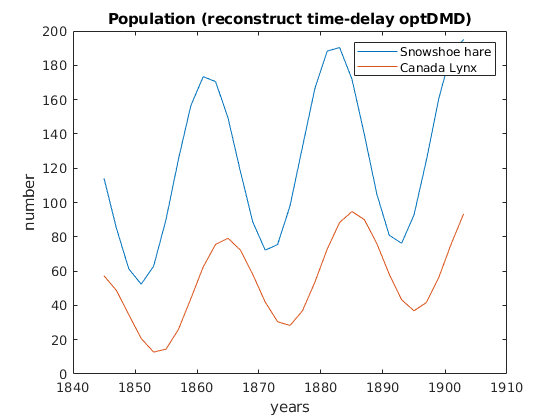

X_rec_optdmd_modes = w_odmd*diag(b_odmd)*exp((lambda_odmd)*[0:length(years)-1]);
X_rec_optdmd = sum(X_rec_optdmd_modes([1:2:complete_rank],:));
X_rec_optdmd = [X_rec_optdmd; sum(X_rec_optdmd_modes([2:2:complete_rank],:))];

figure()
plot(years, real(X_rec_optdmd));
xlabel("years")
ylabel("number")
title("Population (reconstruct time-delay optDMD)")
legend("Snowshoe hare","Canada Lynx")

And with a reduced rank in order to reduce the information

reduced_rank = 2*2;
[w_rodmd,lambda_rodmd,b_rodmd] = optdmd(H,[0:dt:size(H,2)*dt-1],reduced_rank,mode);

step 1 err 1.480275e+05 lambda 3.333333e-01
step 2 err 1.403590e+05 lambda 1.111111e-01
step 3 err 1.245284e+05 lambda 3.703704e-02
step 4 err 1.106678e+05 lambda 1.234568e-02
step 5 err 8.771032e+04 lambda 8.090864e+02
step 6 err 7.239266e+04 lambda 4.408185e+02
step 7 err 3.629138e+04 lambda 1.469395e+02
step 8 err 3.398716e+04 lambda 2.938790e+02
step 9 err 3.291070e+04 lambda 9.795967e+01
step 10 err 3.283481e+04 lambda 3.918387e+02
step 11 err 3.272904e+04 lambda 1.306129e+02
step 12 err 3.265234e+04 lambda 4.353763e+01
step 13 err 3.262193e+04 lambda 1.451254e+01
step 14 err 3.262012e+04 lambda 4.837514e+00
step 15 err 3.261999e+04 lambda 1.612505e+00
step 16 err 3.261993e+04 lambda 5.375016e-01
step 17 err 3.261991e+04 lambda 1.791672e-01
step 18 err 3.261990e+04 lambda 5.972240e-02
step 19 err 3.261989e+04 lambda 1.990747e-02
step 20 err 3.261989e+04 lambda 6.635822e-03
step 21 err 3.261989e+04 lambda 2.211941e-03
step 22 err 3.261989e+04 lambda 7.373136e-04
step 23 err 3.26198

period_rodmd = (1./(imag(lambda_rodmd)/(2*pi*2)))

period_rodmd =   394.4565
 -394.4565
   20.6146
  -20.6146


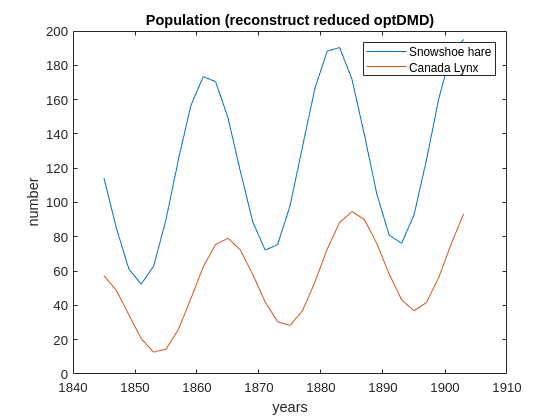

X_rec_roptdmd_modes = w_rodmd*diag(b_rodmd)*exp((lambda_rodmd)*[0:length(years)-1]);
X_rec_roptdmd = sum(X_rec_roptdmd_modes([1:2:complete_rank],:));
X_rec_roptdmd = [X_rec_roptdmd; sum(X_rec_roptdmd_modes([2:2:complete_rank],:))];

figure()
plot(years, real(X_rec_roptdmd));
xlabel("years")
ylabel("number")
title("Population (reconstruct reduced optDMD)")
legend("Snowshoe hare","Canada Lynx")

And finally we can try to apply bagging to this time delay series:

num_p =  50;
num_bag = 10;
lambda_vet = zeros(complete_rank,num_p); 
v = [0:dt:length(years)*dt-time_delay-1];
for ii = 1:num_p
    columns = sort(randperm(size(H,2),num_bag)); % returns a row vector containing k unique integers selected randomly from 1 to n.
    X_red = H(:,columns); % taken data
    years_red = v(columns);
    [w_jbodmd,lambda_jbodmd,b_jbodmd] = optdmd(X_red,years_red,complete_rank,mode,varpro_opts('ifprint',0),lambda_odmd);
    lambda_vet(:,ii) = lambda_jbodmd;
    % media anche du autovettori
end

lambda_vet

lambda_vet =    0.0136 + 0.0244i  -0.0576 + 0.0000i  -0.0078 + 0.0000i  -0.0465 - 0.0000i   0.0243 - 0.0000i   0.0578 + 0.0343i  -0.0040 + 0.0599i  -0.0180 + 0.0355i  -0.0457 + 0.0002i  -0.0128 + 0.0478i  -0.0255 + 0.0000i  -0.0098 + 0.0430i   0.0294 + 0.0289i   0.0245 + 0.0717i  -0.2339 + 0.0009i   0.0070 + 0.0000i  -0.0082 - 0.0000i  -0.0106 + 0.0388i  -0.0054 + 0.0537i  -0.0129 + 0.0000i   0.4796 + 0.0857i  -0.0243 + 0.0358i  -0.5140 + 0.0000i  -0.0214 + 0.0302i   0.0116 + 0.0000i  -0.0077 - 0.0007i   0.0129 - 0.0000i   0.0951 + 0.0004i   0.0536 - 0.0008i  -0.3250 - 0.0005i  -0.0383 + 0.0000i   0.0201 + 0.0384i   0.0580 + 0.0475i  -0.0296 + 0.0276i  -2.4246 + 0.0006i   0.0162 - 0.0000i  -0.0222 + 0.0029i  -0.0071 + 0.0000i  -0.0206 + 0.0379i   0.0078 + 0.0701i  -0.0031 + 0.0017i  -0.0346 + 0.0533i  -0.0258 - 0.0000i  -0.0078 + 0.0361i  -0.0962 + 0.0000i   0.2219 + 0.0001i   0.3519 - 0.0001i  -0.0127 + 0.0437i   0.0086 + 0.0000i   0.0179 + 0.0002i
   0.0136 - 0.0244i  -0.0576 - 0.000

histfit(1./(imag(lambda_vet(1,:))/(2*pi*2)))
title("Eigenvalues imag distribution")
str_e = sprintf('mean=%0.2f variance=%0.2f',(mean(1./(imag(lambda_vet(2,:))/(2*pi*2)))),(var(1./(imag(lambda_vet(2,:))/(2*pi*2)))))

str_e = 'mean=-127114249.47 variance=567261050141662336.00'

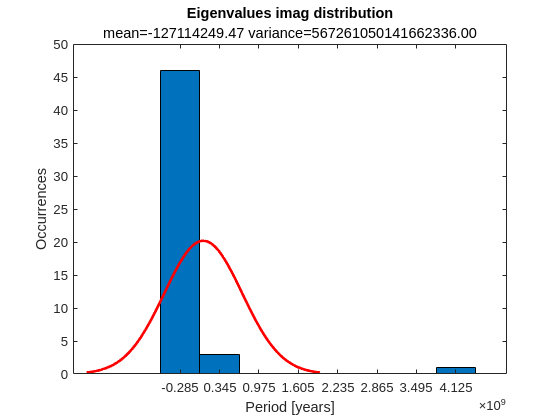

%subtitle(["mean=",num2str(mean(1./(imag(lambda_vet(2,:))/(2*pi*2)))),", variance=",num2str(var(1./(imag(lambda_vet(2,:))/(2*pi*2)))),")"])
subtitle(str_e)
ylabel("Occurrences")
xlabel("Period [years]")

histfit(real(lambda_vet(1,:)))
title('Eigenvalues real distribution')
str_e = sprintf('mean=%0.4f variance=%0.4f',(mean(imag(lambda_vet(2,:)))),(mean(real(lambda_vet(2,:)))))

str_e = 'mean=-0.0141 variance=0.0238'

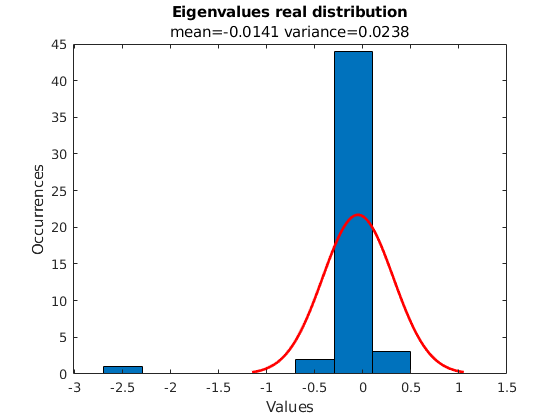

subtitle(str_e)
ylabel("Occurrences")
xlabel("Values")



mean_result = mean((lambda_vet'))';
period_bodmd = 1./(imag(mean_result)/(2*pi*2))

period_bodmd =   661.8452
 -892.6652
   20.6548
  -20.6555


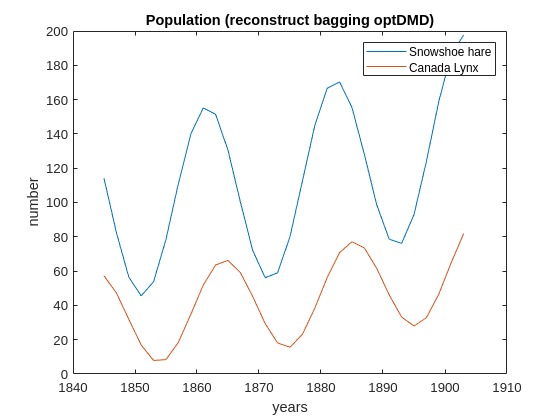



X_rec_boptdmd_modes = w_odmd*diag(b_odmd)*exp((mean_result)*[0:length(years)-1]);
X_rec_boptdmd = sum(X_rec_boptdmd_modes([1:2:complete_rank],:));
X_rec_boptdmd = [X_rec_boptdmd; sum(X_rec_boptdmd_modes([2:2:complete_rank],:))];
figure()
plot(years, real(X_rec_boptdmd));
xlabel("years")
ylabel("number")
title("Population (reconstruct bagging optDMD)")
legend("Snowshoe hare","Canada Lynx")

To check the energy contribution of each mode.

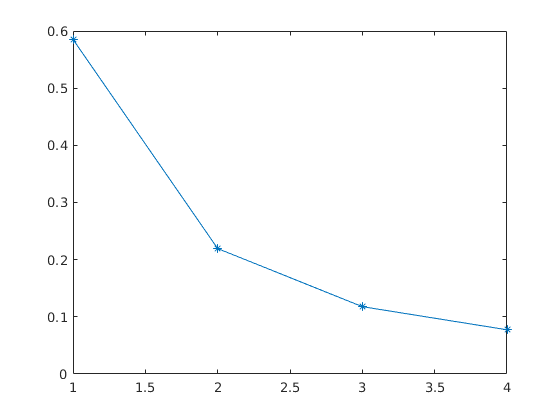

[U,Sigma,V] = svd(H,'econ');
ene =diag(Sigma)/sum(diag(Sigma));
plot(ene,'*-')
hold on

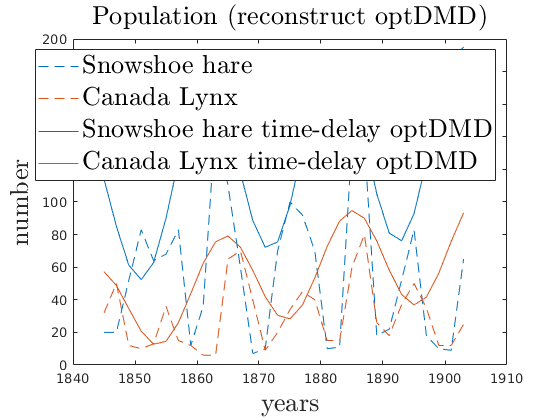

%plot(,'*r')

figure()
plot(years, real(X(1,:)),'--', 'Color',[0 0.4470 0.7410]);
hold on
plot(years, real(X(2,:)),'--', 'Color',[0.8500 0.3250 0.0980]);
plot(years, real(X_rec_optdmd(1,:)),'-', 'Color',[0 0.4470 0.7410]);
plot(years, real(X_rec_optdmd(2,:)),'-', 'Color',[0.8500 0.3250 0.0980]);
extraInputs = {'interpreter','latex','fontsize',20}; % name, value pairs
xlabel("years",extraInputs{:})
ylabel("number",extraInputs{:})
title("Population (reconstruct optDMD)",extraInputs{:})
legend("Snowshoe hare","Canada Lynx","Snowshoe hare time-delay optDMD","Canada Lynx time-delay optDMD",extraInputs{:})

## Definition of exact DMD

function [Phi, Lambda, b] = DMD(X,Xprime,r)
[U,Sigma,V] = svd(X,'econ');
Ur = U(:,1:r);
Sigmar = Sigma(1:r,1:r);
Vr = V(:,1:r);
Atilde = (Ur)'*Xprime*Vr/Sigmar;
[W,Lambda] = eig(Atilde); 
Phi = Xprime*(Vr/Sigmar)*W;
alpha1 = Sigmar*Vr(1,:)';
b = (W*Lambda)\alpha1;
end

## Definition of Hankel matrix function

function H = hank(A, n)
    r = size(A,1);
    c = size(A,2);
    H = zeros(r*n, c - n + 1);
    for ii = 1:n
        H((ii-1)*r+1:ii*r,:) = [A(:,ii:c + ii - n)];
    end
end